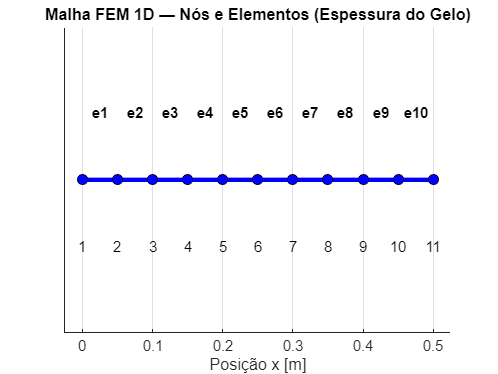

%% Projeto Computacional - Modelação Computacional Avançada
% Primeira Discretização: Método dos Elementos Finitos (FEM) em 1D
% Problema de Stefan (Fatia Térmica do Gelo)

clear 
close all 
clc

%% 1. Parâmetros Físicos e Geométricos
k_gelo = 2.22;        % Condutividade térmica do gelo [W/(m·K)]
qdot = 0;             % Sem fonte interna de calor (ou valor de transição se aplicável)
L = 0.5;              % Espessura total do bloco de gelo na direção do fluxo [m]

% Condições de Fronteira (Dirichlet)
T_sup = 293.15;       % Temperatura na superfície exposta ao aquecimento (20 ºC) [K]
T_inf = 268.15;       % Temperatura na base/interior do gelo (-5 ºC) [K]

%% 2. Definição da Malha FEM 1D (Discretização Espacial)
Ne = 10;              % Número de elementos (podes alterar para testar convergência)
N_nos = Ne + 1;       % Número de nós
x = linspace(0, L, N_nos);   % Coordenadas dos nós (malha uniforme)

% Matriz de Conectividade (associa cada elemento e aos seus dois nós globais)
elem = zeros(Ne, 2);
for e = 1:Ne
    elem(e, 1) = e;
    elem(e, 2) = e + 1;
end

%% 2.1. Representação Gráfica da Malha (Mesh 1D)
figure('Name', 'Malha FEM 1D', 'Color', 'white');
hold on

% Desenhar os elementos finitos (linhas azuis)
for e = 1:Ne
    nos = elem(e, :);
    plot(x(nos), [0 0], '-b', 'LineWidth', 3);
    text(mean(x(nos)), 0.035, sprintf('e%d', e), ...
        'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
end

% Desenhar os nós (pontos pretos com centro azul)
plot(x, zeros(size(x)), 'ok', ...
    'MarkerFaceColor', 'b', 'MarkerSize', 7);

% Numerar os nós por baixo da linha
for i = 1:N_nos
    text(x(i), -0.035, sprintf('%d', i), ...
        'HorizontalAlignment', 'center', 'FontSize', 10);
end

% Configurações do gráfico da malha
xlabel('Posição x [m]');
title('Malha FEM 1D — Nós e Elementos (Espessura do Gelo)');
ylim([-0.08 0.08]);
xlim([-0.05*L 1.05*L]);
yticks([]);
grid on
hold off


%% 3. Inicialização do Sistema Global (Rigidez e Fontes)
K = zeros(N_nos, N_nos);       % Matriz global de rigidez K
F = zeros(N_nos, 1);           % Vetor global de fontes F

%% 4. Cálculo Elementar e Assemblagem Global (K * T = F)
for e = 1:Ne
    % Nós globais do elemento atual
    nos = elem(e, :);          
    
    % Comprimento do elemento (he)
    he = x(nos(2)) - x(nos(1));              

    % Matriz de rigidez elementar (Ke) - idêntica à deduzida na aula TP#5
    Ke = (k_gelo / he) * [1, -1; -1, 1];
    
    % Vetor de fontes elementar (fe)
    fe = (qdot * he / 2) * [1; 1];  

    % Assemblagem na matriz global e vetor global
    K(nos, nos) = K(nos, nos) + Ke;
    F(nos) = F(nos) + fe;
end

%% 5. Aplicação das Condições de Fronteira (Dirichlet)
% Nós fixos (fronteiras) e nós livres (interior)
nos_fixos = [1, N_nos];                   
nos_livres = setdiff(1:N_nos, nos_fixos); 

% Vetor de temperaturas completo inicializado com as fronteiras fixas
T = zeros(N_nos, 1);
T(1) = T_sup;       % T(0) na superfície
T(N_nos) = T_inf;   % T(L) no interior

% Particionamento do sistema para resolver apenas os nós livres
F_livres = F(nos_livres) - K(nos_livres, nos_fixos) * T(nos_fixos);
K_livres = K(nos_livres, nos_livres);

% Resolução do sistema linear reduzido
T(nos_livres) = K_livres \ F_livres;

%% 6. Verificação e Validação da Solução
fprintf('--- VERIFICAÇÃO DA DISCRETIZAÇÃO ---\n');

--- VERIFICAÇÃO DA DISCRETIZAÇÃO ---


fprintf('Temperatura na superfície T(0) = %.2f K (Esperado: %.2f K)\n', T(1), T_sup);

Temperatura na superfície T(0) = 293.15 K (Esperado: 293.15 K)


fprintf('Temperatura na base T(L) = %.2f K (Esperado: %.2f K)\n', T(end), T_inf);

Temperatura na base T(L) = 268.15 K (Esperado: 268.15 K)


fprintf('Erro de simetria da matriz global K: %.3e\n\n', norm(K - K', 'fro'));

Erro de simetria da matriz global K: 0.000e+00



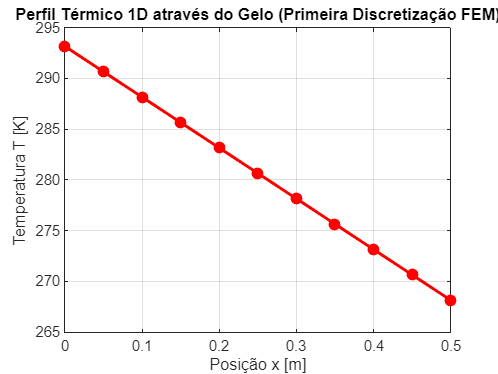


%% 7. Representação Gráfica do Perfil Térmico
figure('Name', 'Perfil de Temperatura 1D - FEM');
plot(x, T, '-ro', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'r');
grid on;
xlabel('Posição x [m]');
ylabel('Temperatura T [K]');
title('Perfil Térmico 1D através do Gelo (Primeira Discretização FEM)');